# COVID-19 Detection Using X-Rays

by Joshua Rothe

## Image pre-processing, K-Means

K = 3;  % for K-means

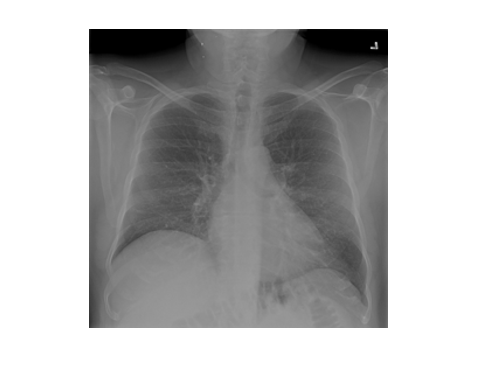

% Class - normal images
num_images = 2000;
normal_img = zeros((299*299),num_images);   % Initialize empty array
for i = 1:num_images
    filename = sprintf('./data/normal/Normal-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    % img = imsegkmeans(img,K);
    normal_img(:,i) = double(reshape(img,[],1));    % reshapes image as column vector
end                                                 % and adds it to normal_img
labels(1:num_images,1) = "normal";
imshow(img);

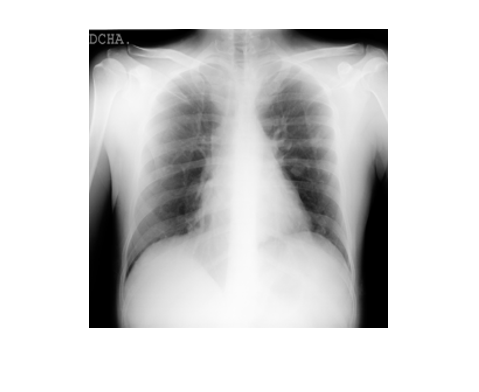

% Class - COVID
num_images2 = 1000;
cov_img = zeros((299*299),num_images2);  % Initialize empty array
for i = 1:num_images2
    filename = sprintf('./data/COVID/COVID-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    % img = imsegkmeans(img,K);
    cov_img(:,i) = double(reshape(img,[],1));       % reshapes image as column vector
end                                                 % and adds it to cov_img
labels(num_images+1:num_images2+num_images,1) = "COVID";
imshow(img);

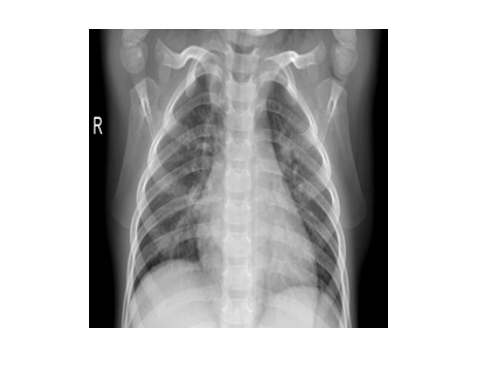

% Class - Viral Pneumonia images
num_images3 = 1000;
pnu_img = zeros((299*299),num_images3);   % Initialize empty array
for i = 1:num_images3
    filename = sprintf('./data/Viral Pneumonia/Viral Pneumonia-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    % img = imsegkmeans(img,K);
    pnu_img(:,i) = double(reshape(img,[],1));   % reshapes image as column vector
end                                             % and adds it to pnu_img
labels(num_images+num_images2+1:num_images+num_images2+num_images3,1) = "viral pneumonia";                  
imshow(img);

% Combine images and labels
train_images = [normal_img, cov_img, pnu_img];
train_labels = labels;

## Apply PCA

%% Train and find the PCA dimensions of the training data
% First reduce the training data to a computationally manageable size
% (note: in this instance, size is unchanged, but may adjust as needed)
train_size = num_images + num_images2 + num_images3;
base = 50;         % Base size, given
% Reduced variables are for if we reduce the number if pics taken from
% dataset.
train_images_reduced = train_images(:,[1:train_size]);
train_labels_reduced = train_labels([1:train_size],:);
% Normalize the data, will be calling it X for simplicity
X = train_images_reduced;
Xmean = mean(X);    % mean of X
Xnorm = X - Xmean;  % normalized
% Calculate covariance matrix
covar_matrix = (Xnorm' * Xnorm) / (train_size - 1);
% Calculate Eigenvectors and Eigenvalues of Covariance Matrix
[Xeivec, Xeival] = eig(covar_matrix);
% Now project the dataset
proj_train = Xnorm * Xeivec;
% Back into larger data format
Xnormk_train = proj_train * Xeivec';

## Optimize Models

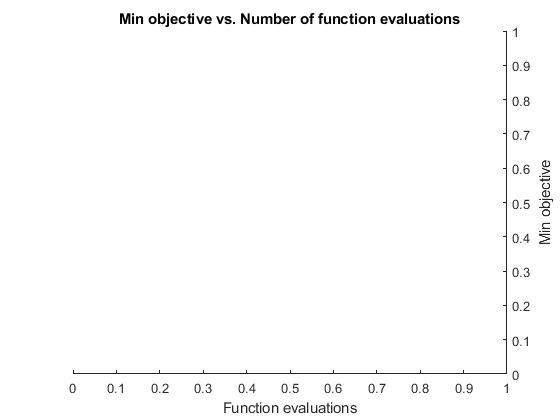

% Find optimised numbers using MATLAB
Mdl_opt_pnu = fitcecoc(Xnormk_train',train_labels_reduced','OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus'))